# Atividade 06_01

Otávio Baziewicz Filho - 1942808    

## Clear Workspace

clear all;
close all;
clc;

## Structural Similarity (SSIM)

Nesta atividade, você deve elaborar um script MATLAB para reproduzir a parte da ‘Demonstration’ do método em https://ece.uwaterloo.ca/~z70wang/research/ssim, em que são calculados o MSE e o índice SSIM para as seis imagens do Einstein. Estas seis imagens necessárias para a atividade estão disponíveis no arquivo IF69D_ATV_06_arquivos.zip (einstein.gif é a original).

Em https://ece.uwaterloo.ca/~z70wang/research/ssim/#usage há o código do índice SSIM, que foi usado para a ‘Demonstration’ mostrada no site. Se preferir, é possível também usar a função **ssim** do MATLAB com os parâmetros default. Por exemplo: **qs = ssim(Ia, Ib);**. Para obter o MSE (mean squared error), a função do MATLAB é a **immse**. Por exemplo:** qe = immse(Ia, Ib);**.

einsteinImg = imread("einstein.gif");
blurImg = imread("blur.gif");
contrastImg = imread("contrast.gif");
impulseImg = imread("impulse.gif");
jpgImg = imread("jpg.gif");
meanshiftImg = imread("meanshift.gif");

mseEinsteinImg = immse(einsteinImg, einsteinImg);
ssimEinsteinImg = ssim(einsteinImg, einsteinImg);

mseBlurImg = immse(einsteinImg, blurImg);
ssimBlurImg = ssim(einsteinImg, blurImg);

mseContrastImg = immse(einsteinImg, contrastImg);
ssimContrastImg = ssim(einsteinImg, contrastImg);

mseImpulseImg = immse(einsteinImg, impulseImg);
ssimImpulseImg = ssim(einsteinImg, impulseImg);

mseJpgImg = immse(einsteinImg, jpgImg);
ssimJpgImg = ssim(einsteinImg, jpgImg);

mseMeanshiftImg = immse(einsteinImg, meanshiftImg);
ssimMeanshiftImg = ssim(einsteinImg, meanshiftImg);

% Figures

figure, imshow(einsteinImg)

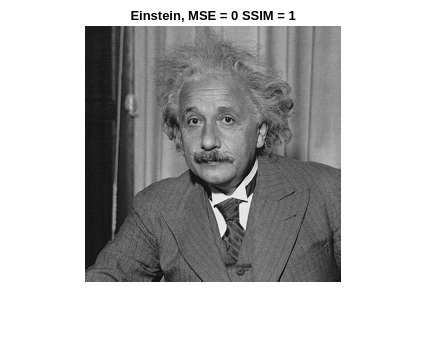

title("Einstein, MSE = " + round(mseEinsteinImg) + " SSIM = " + round(ssimEinsteinImg, 3))

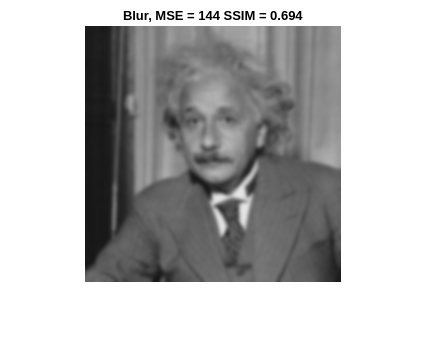


figure, imshow(blurImg)
title("Blur, MSE = " + round(mseBlurImg) + " SSIM = " + round(ssimBlurImg, 3))

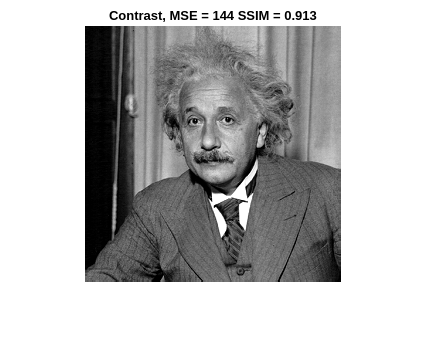


figure, imshow(contrastImg)
title("Contrast, MSE = " + round(mseContrastImg) + " SSIM = " + round(ssimContrastImg, 3))

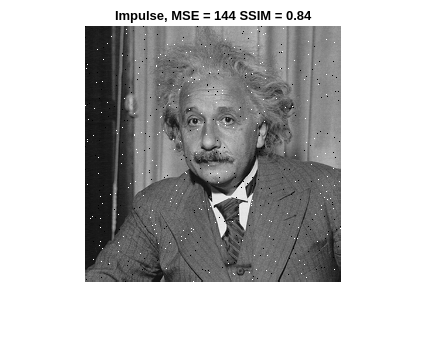


figure, imshow(impulseImg)
title("Impulse, MSE = " + round(mseImpulseImg) + " SSIM = " + round(ssimImpulseImg, 3))

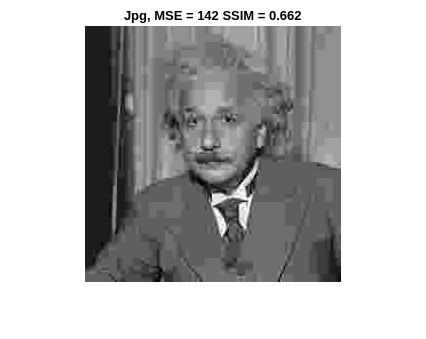


figure, imshow(jpgImg)
title("Jpg, MSE = " + round(mseJpgImg) + " SSIM = " + round(ssimJpgImg, 3))

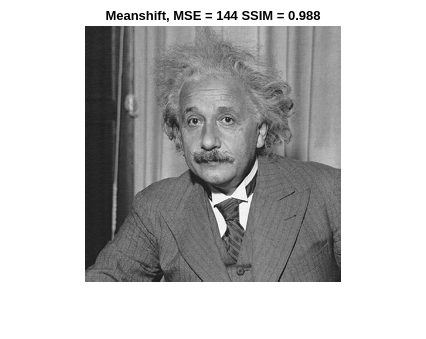


figure, imshow(meanshiftImg)
title("Meanshift, MSE = " + round(mseMeanshiftImg) + " SSIM = " + round(ssimMeanshiftImg, 3))

### a) A ‘Demonstration’ foi reproduzida com sucesso?

Sim, os valores reais de SSIM e MSE foram arredondados nos plot e assim os resultados ficaram idênticos. O plot foi feito separadamente para melhor visualização das imagens.

### b) Por que o índice SSIM é melhor que o MSE neste experimento?

Um valor menor de MSE indica uma similaridade maior entre as imagens comparadas. Aplicar SSIM ao invés do MSE para comparar essas imagens é melhor nesse caso pois o MSE leva em consideração o a soma média dos erros de cada pixel, e não a estrutura da imagem, como o caso do SSIM. A média dos erros de cada pixel é muito parecida entre as imagens, mas a estrutura das imagens não é.